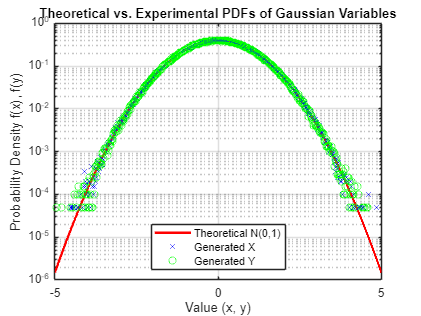

clear; clc; close all;

% Load the generated data
X = load('X_samples.txt');
Y = load('Y_samples.txt');

% Define bins for the histogram

bin_edges = -5:0.02:5; 

bin_centers = bin_edges(1:end-1) + 0.01;


fx = histcounts(X, bin_edges, 'Normalization', 'pdf');
fy = histcounts(Y, bin_edges, 'Normalization', 'pdf');


z = -5:0.001:5;

fz = exp(-z.^2 / 2) / sqrt(2*pi);

% Plot the results
figure;
% Plot on a logarithmic y-axis to better see the tails of the distribution
semilogy(z, fz, 'r', 'LineWidth', 2); % Theoretical PDF in red
hold on;
semilogy(bin_centers, fx, 'bx');   % Empirical PDF of X as blue 'x' markers
semilogy(bin_centers, fy, 'go');   % Empirical PDF of Y as green 'o' markers
hold off;

% Add labels and a legend
grid on;
title('Theoretical vs. Experimental PDFs of Gaussian Variables');
xlabel('Value (x, y)');
ylabel('Probability Density f(x), f(y)');
legend('Theoretical N(0,1)', 'Generated X', 'Generated Y', 'Location', 'south');
xlim([-5 5]);